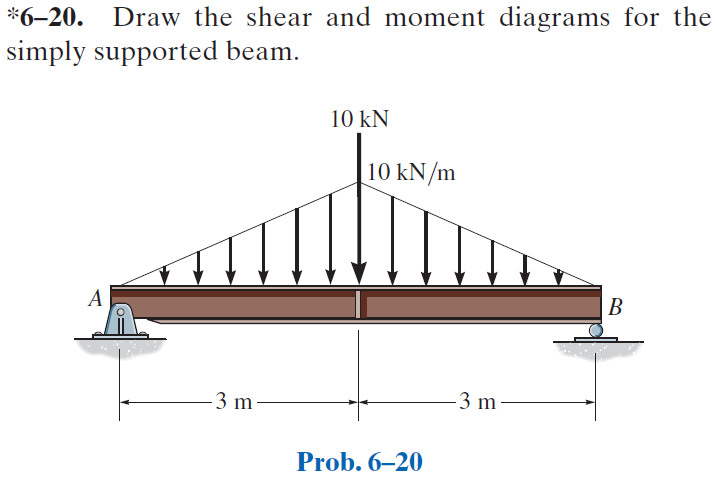

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-20P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-20P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# distributed load formulas

w1 = findpoly(1, 'thru', [0 0], 'thru', [3*u.m -10*u.kN/u.m]);
w2 = findpoly(1, 'thru', [3*u.m -10*u.kN/u.m], 'thru', [6*u.m 0]);

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 6*u.m);
b = b.add('concentrated', 'force', -10*u.kN, 3*u.m);
b = b.add('distributed', 'force', w1, [0 3]*u.m);
b = b.add('distributed', 'force', w2, [3 6]*u.m, [false true]);
b.L = 6*u.m;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(x^{4}-120\,x^{2}\,m^{2}+2835\,m^{4}\right)}{36\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }x\leq 3\,m\\ \frac{\left(x-6\,m\right)\,\left(x^{4}-24\,x^{3}\,m+96\,x^{2}\,m^{2}+576\,x\,m^{3}-189\,m^{4}\right)}{36\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }3\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{5\,\left(x-3\,m\right)\,\left(x+3\,m\right)\,\left(63\,m^{2}-x^{2}\right)}{36\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }x\leq 3\,m\\ -\frac{5\,\left(x-3\,m\right)\,\left(x-9\,m\right)\,\left(-x^{2}+12\,x\,m+27\,m^{2}\right)}{36\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }3\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{5\,x\,\left(x-6\,m\right)\,\left(x+6\,m\right)}{9}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }x\leq 3\,m\\ \frac{5\,x\,\left(x-6\,m\right)\,\left(x-12\,m\right)}{9}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }3\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{5\,\left(12\,m^{2}-x^{2}\right)}{3}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }x\leq 3\,m\\ \frac{5\,\left(x^{2}-12\,x\,m+24\,m^{2}\right)}{3}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }3\,m<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -\frac{10\,x}{3}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }x\leq 3\,m\\ \frac{10\,\left(x-6\,m\right)}{3}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }3\,m<x \end{array}\right.$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & 20\,\mathrm{kN}\\ \mathrm{Rb} & 20\,\mathrm{kN} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

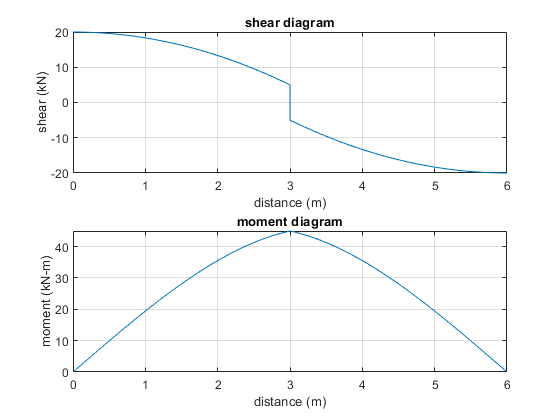

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

# clean up

addvar(y);
assume(old_assum);
clear old_assum;